deltat = 0.00001;
deltax = 0.2;
T = 1575000;
A = pi*(0.029)^2;
rho = 7.58;
c = sqrt(T/(rho*A));
delta = (c^2)*((deltat)^2)/((deltax)^2);
t = 0:deltat:(3/440);
x = deltax:deltax:(10-deltax);
N_t = length(t);
N_x = length(x);
u = zeros(N_x,N_t);
I = eye(N_x);
D2 = zeros(N_x,N_x);
D2(1,:) = [-2,1,zeros(1,47)];
D2(2,:) = [1,-2,1,zeros(1,46)];
D2(N_x-1,:) = [zeros(1,46),1,-2,1];
D2(N_x,:) = [zeros(1,47),1,-2];
for i=3:1:(N_x)-2
    D2(i,:) = [zeros(1,i-2),1,-2,1,zeros(1,(N_x)-(1+i))];
end
for i=1:1:N_x
    u(i,1) = sin(pi*x(i)/10);
end
u(:,2) = ((delta*D2)*(u(:,1)) + 2*u(:,1))/2;
for i=2:1:N_t-1
    u(:,i+1) = (delta*D2)*u(:,i) + 2*u(:,i) - u(:,i-1);
end

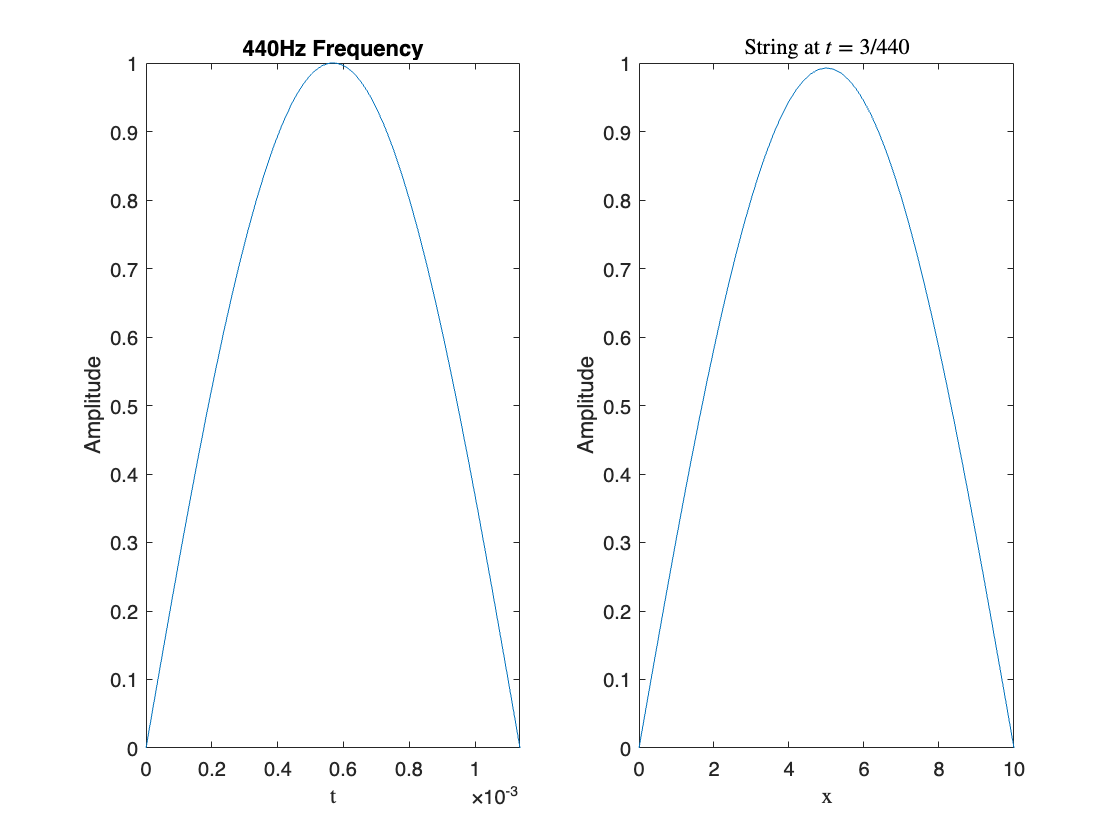

u = [zeros(1,N_t);u;zeros(1,N_t)];
x = [0,x,10];
subplot(1,2,1);
syms y;
f = sin(pi*2*440*y);
fplot(f,[0,3/(440*6)]);
hold on;
title('440Hz Frequency');
xlabel('t', 'interpreter', 'latex');
ylabel('Amplitude');
subplot(1,2,2);
plot(x,u(:,N_t));
title('String at $t = 3/440$', 'interpreter', 'latex');
xlabel('x','interpreter', 'latex');
ylabel('Amplitude');

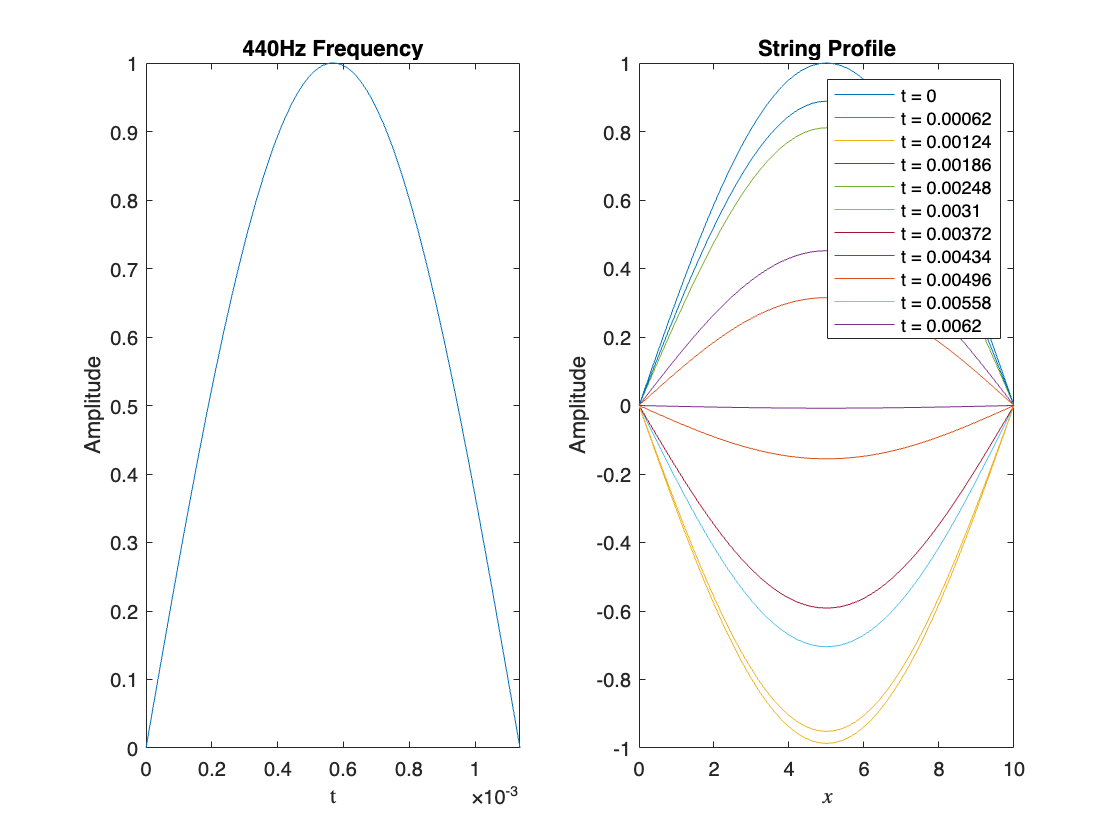

n = 1:62:N_t;
for i=1:62:N_t
    txt = ['t = ', num2str(t(i))];
    plot(x,u(:,i),'DisplayName', txt);
    hold on;
end
title('String Profile');
xlabel('$x$', 'interpreter', 'latex');
ylabel('Amplitude');
legend show;